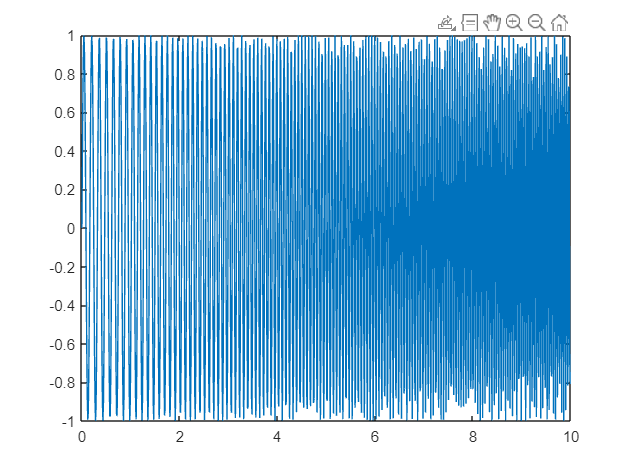

%prob1
Fs=100;
t=0:1/Fs:10-1/Fs;
f=linspace(4,10,1000);
x= sin(2*pi.*f.*t);

figure;
plot(t,x)

y=abs(fft(x));
F= (0:length(y)-1)*Fs/length(x);
plot(F,y)

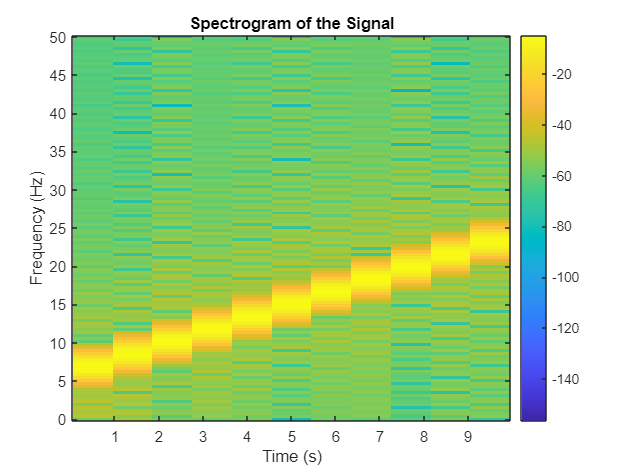

% threshold =  max(y);   % Set a threshold for peak detection
% peaks = find(y >= threshold); % Find indices of peaks
% peak_frequencies = F(peaks); % Extract peak frequencies
% 
% % Display the identified frequency components
% disp('Identified Frequency Components:');
% disp(peak_frequencies);
window_length = 100;   % Length of the Hamming window (samples)
overlap = 10;          % Overlap between consecutive windows (samples)

% Compute and plot the spectrogram
figure;
spectrogram(x, hamming(window_length), overlap, [], Fs,'yaxis');
title('Spectrogram of the Signal');
xlabel('Time (s)');
ylabel('Frequency (Hz)');
colorbar;

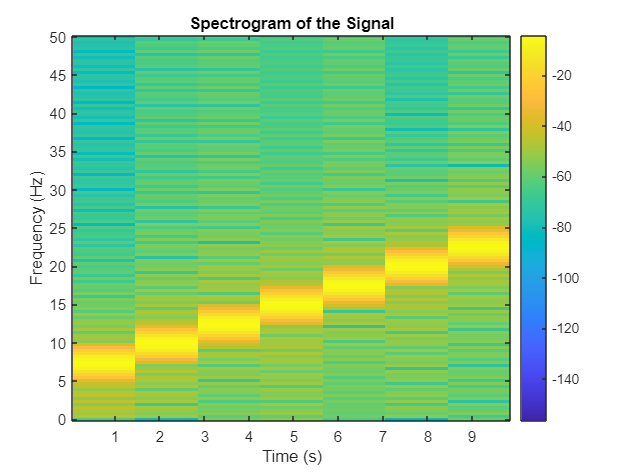

spectrogram(x, hamming(150), overlap, [], Fs,'yaxis');
title('Spectrogram of the Signal');
xlabel('Time (s)');
ylabel('Frequency (Hz)');
colorbar;

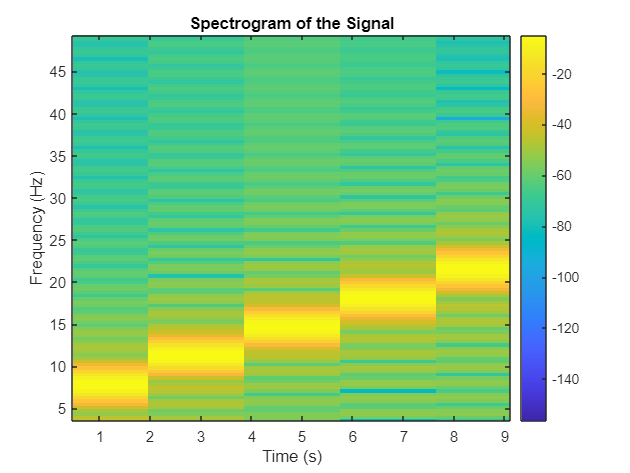

spectrogram(x, hamming(200), overlap, [], Fs,'yaxis');
title('Spectrogram of the Signal');
xlabel('Time (s)');
ylabel('Frequency (Hz)');
colorbar;

% %prob1
% Fs=100;
% t=0:1/Fs:10-1/Fs;
% f=linspace(4,10,1000);
% x= sin(2*pi.*f.*t);
% 
% figure;
% 
% plot(t,x)
% title("Chrip Signal")
% ylabel("Amplitude")
% xlabel("Time (s)")
% y=abs(fft(x));
% F= (0:length(y)-1)*Fs/length(x);
% figure;
% plot(F,y)
% title("Fourier Transform of the signal")
% xlabel("Frequency Hz")
% ylabel("Magnitude ")
% % threshold =  max(y);   % Set a threshold for peak detection
% % peaks = find(y >= threshold); % Find indices of peaks
% % peak_frequencies = F(peaks); % Extract peak frequencies
% % 
% % % Display the identified frequency components
% % disp('Identified Frequency Components:');
% % disp(peak_frequencies);
% window_length = 100;   % Length of the Hamming window (samples)
% overlap = 10;          % Overlap between consecutive windows (samples)
% 
% % Compute and plot the spectrogram
% figure;
% spectrogram(x, blackman(window_length), overlap, [], Fs,'yaxis');
% title('Spectrogram of the Signal(window length of 100)');
% 
% xlabel('Time (s)');
% ylabel('Frequency (Hz)');
% colorbar;
% figure;
% spectrogram(x, blackman(150), overlap, [], Fs,'yaxis');
% title('Spectrogram of the Signal(window length of 150)');
% xlabel('Time (s)');
% ylabel('Frequency (Hz)');
% colorbar;
% figure;
% spectrogram(x, blackman(200), overlap, [], Fs,'yaxis');
% title('Spectrogram of the Signal(window length of 200)');
% xlabel('Time (s)');
% ylabel('Frequency (Hz)');
% colorbar;



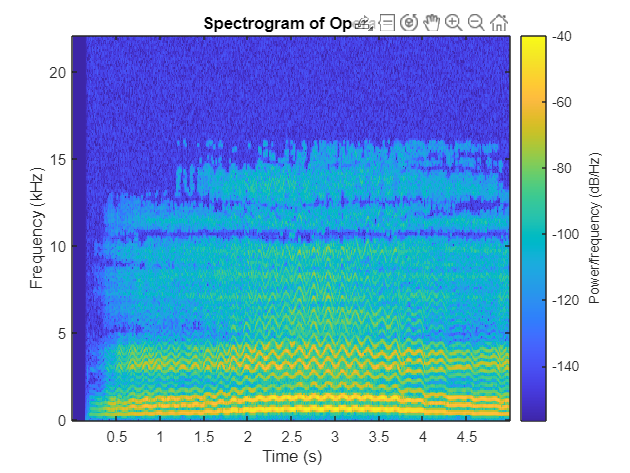

%prob2
clear all;

% Import audio
[y1, fs1] = audioread('instru1.wav');
window_length = 500;
overlap = 30;
figure;
spectrogram(y1, hanning(window_length), overlap, window_length, fs1, 'yaxis');
title("Spectrogram of Instrument 1")



[y2, fs2] = audioread('Opera.wav');
window_length = 500;
overlap = 30;
figure;
spectrogram(y2, hanning(window_length), overlap, window_length, fs2, 'yaxis');
title("Spectrogram of Opera ")

y=abs(fft(y1));
F= (0:length(y)-1)*fs1/length(y1);
figure;
plot(F,y)
title("Fourier Transform of data (Instrument)")
xlabel("Frequency Hz")
ylabel("Magnitude ")



%prob 3
% Set the recording parameters
Fs = 4000; % Sampling rate (Hz)
duration = 1.5; % Recording duration (seconds)

% Record your voice
recorder = audiorecorder(Fs, 16, 1); % 16-bit mono audio
disp('Start speaking...');

Start speaking...


recordblocking(recorder, duration);
disp('Recording finished.');

Recording finished.


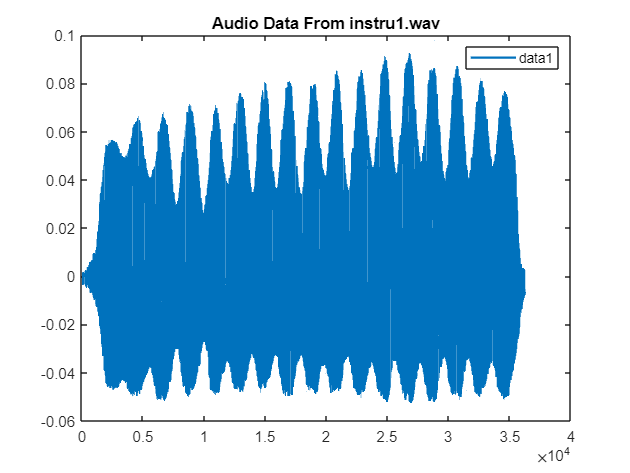


% Get the recorded data
voice_data = getaudiodata(recorder);

% Save the recorded data as a .wav file
audiowrite('your_name.wav', voice_data, Fs);
% Load the recorded audio file
[y, Fs] = audioread('your_name.wav');


% Calculate the spectrogram
figure;
spectrogram(y, hamming(512), 256, [], Fs, 'yaxis');
title('Spectrogram of Your Name Recording');
xlabel('Time (seconds)');
ylabel('Frequency (Hz)');
colorbar;